# **Lab 2**

# Problem 1

We are looking for gamma-ray sources with a telescope similar to the Fermi telescope. In this kind of telescope there is a background of cosmic-rays (electrons and protons, mostly) that provides a discrete noise term across the sky that precisely follows a Poisson distribution. To detect a gamma-ray source, you need to ask what is the probability that the cosmic-ray background would have given you a measurement as signal-like or more than the signal that you received.

## A) Progression of Probability Distribution after Integration over Days

Taking my average cosmic ray background as X = 2.6 and the average number of emmissions from my source as Y = 5.9. Both averages are for 1 day. 

X = 2.6;
Y = 5.9;

Generating my background distribution (Poisson): 

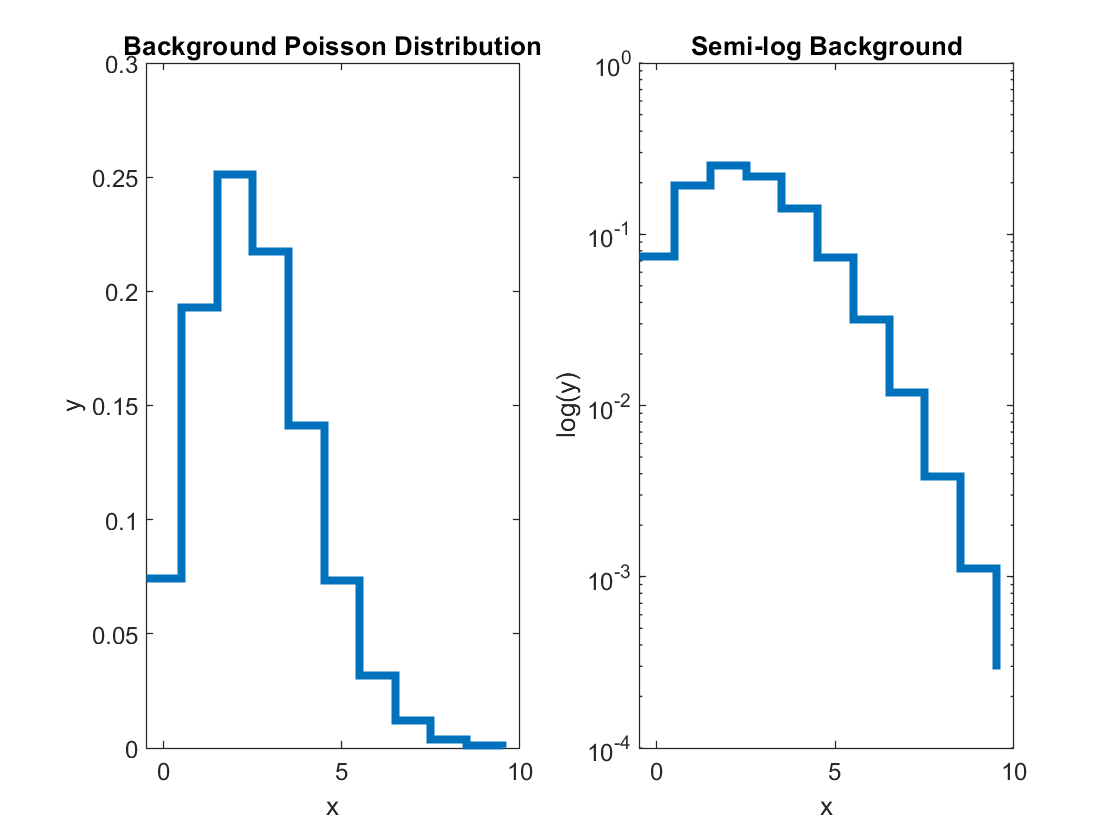


xvals = 0:10;
poisson = makedist("Poisson","lambda",X);
funct = pdf(poisson,xvals);

subplot(1,2,1)
stairs(xvals-0.5,funct,"LineWidth",3)

title('Background Poisson Distribution')
xlabel('x')
ylabel('y')

%semi-log axis
subplot(1,2,2)
stairs(xvals-0.5,funct,"LineWidth",3)
set(gca,'YScale','log')

title('Semi-log Background')
xlabel('x')
ylabel('log(y)')

Summing the distribution over 4 days:

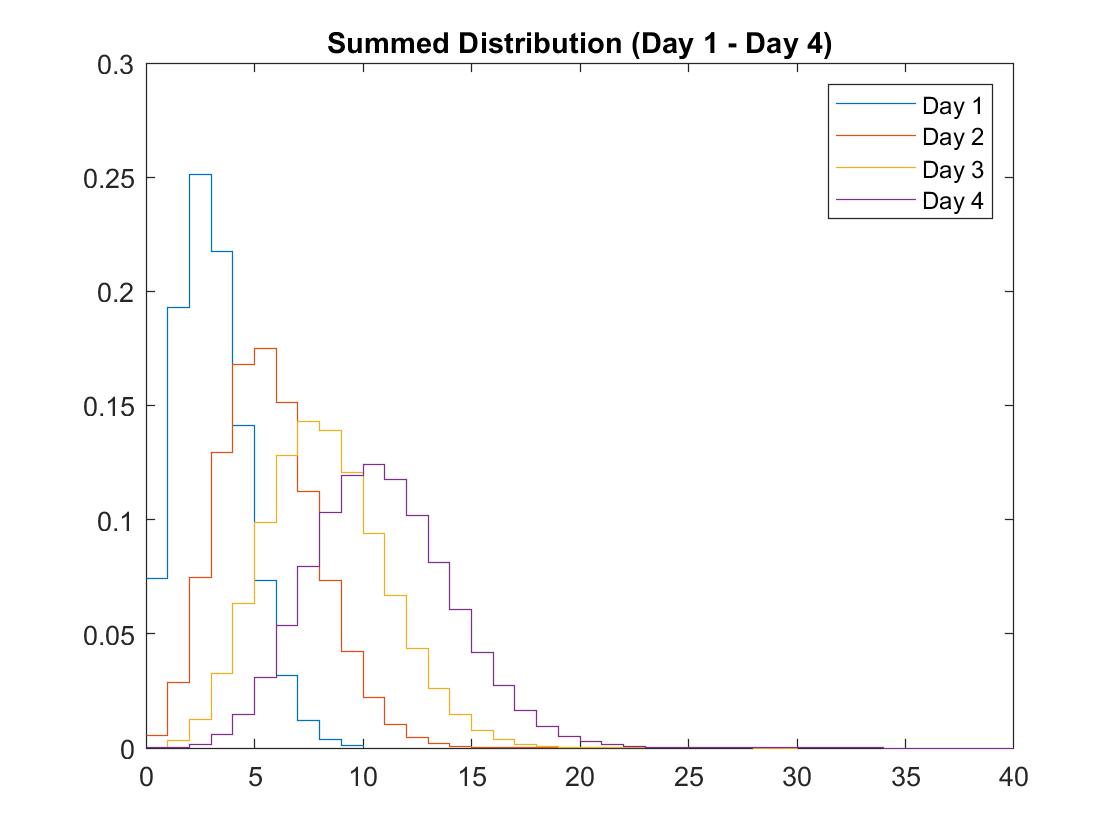

resolution = 1;
xmax = 10;
xmin = 0;
x = xmin:resolution:xmax;

logP = makedist("Poisson",'lambda',X);

base = pdf(logP,x);
base = base/sum(base);
comb = base;

subplot(1,1,1)
stairs(x,base)
hold on

for h = 2:4
    comb = conv(comb,base,"full");
    
    cx = xmin*h:resolution:xmax*h;
    stairs(cx,comb)
end

hold off

legend('Day 1','Day 2','Day 3','Day 4') 
title('Summed Distribution (Day 1 - Day 4)')

The graph shows how the distribution progresses over several days. As time passes, the summed distribution flattens out, moves to the right, and begins to appear more Gaussian. 

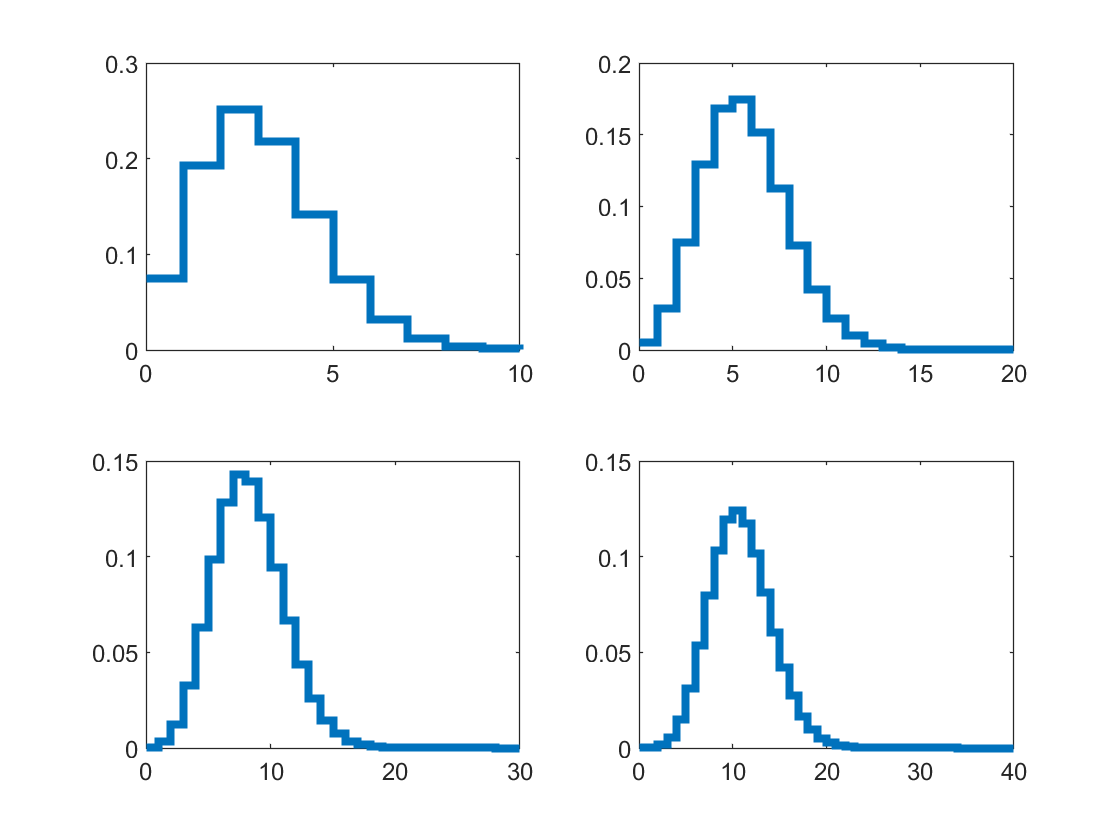

comb = base;

subplot(2,2,1)
stairs(x,base,"LineWidth",3)

for i = 2:4
    comb = conv(comb,base,"full");
    
    subplot(2,2,i)
    cx = xmin*i:resolution:xmax*i;
    stairs(cx,comb,"LineWidth",3)
end

Here you see the distributions individually. 

## B) Probability Distribution after 5 Days

## Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view. 

Convolving my distribution 5 times to model the background distribution on day 5:

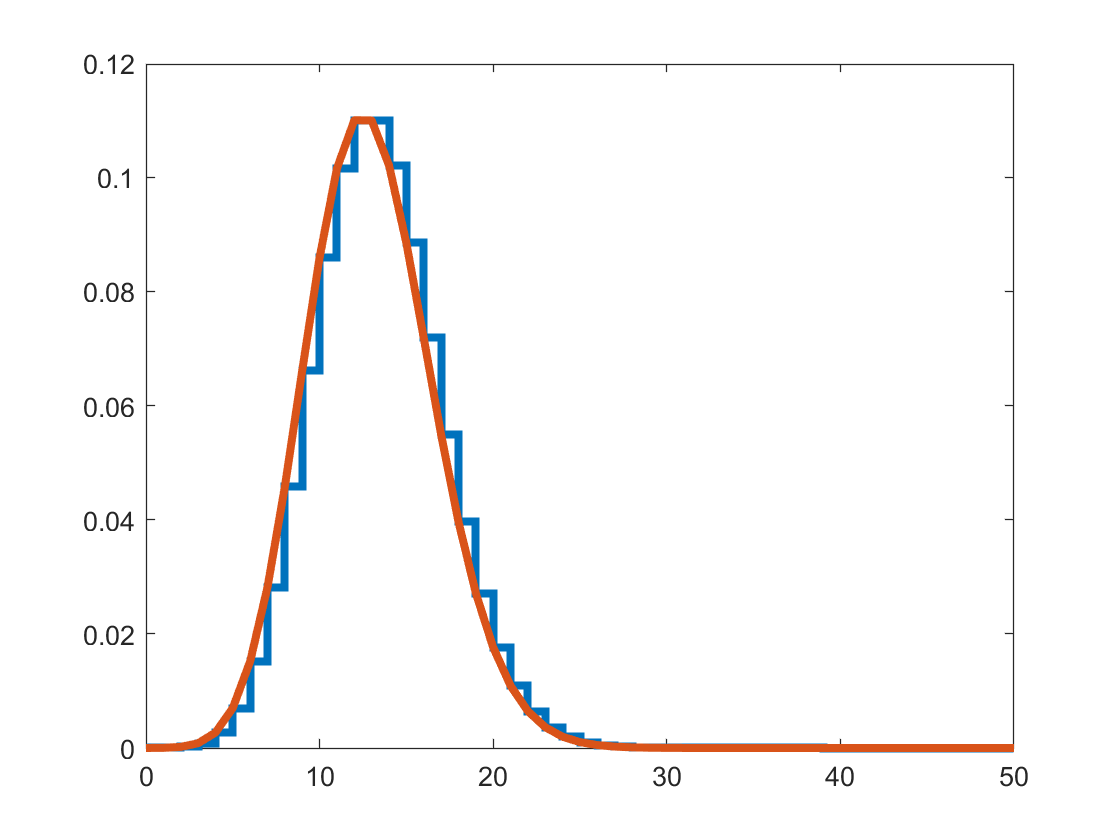

X = 2.6;
Y = 5.9;

res = 1;
xmax_5 = 10;
xmin_5 = 0;
x = xmin_5:res:xmax_5;

logP = makedist("Poisson",'lambda',X);

base = pdf(logP,x);
base = base/sum(base);
comb = base;

for j = 2:5
    comb = conv(comb,base,"full");
end

subplot(1,1,1)
cx_5 = xmin_5*j:res:xmax_5*j;
stairs(cx_5,comb,"LineWidth",3)
hold on

weighted_5 = zeros(1,length(cx_5));

for k = 1:length(cx_5)
    weighted_5(k) = comb(k)*cx_5(k);
end

lambda = sum(weighted_5);

poisson_5 = makedist("Poisson","lambda",lambda);
plot(cx_5,pdf(poisson_5,cx_5),"LineWidth",3)
hold off

I've overlayed a poisson distribution with the same average value "lambda" as I calculated from my Day 5 distribution. It matches perfectly with the convolution, indicating that the distribution remains a Poisson distribution even after summing over 5 days. 

This makes sense, since ....................................

Explain why this makes sense from a mathematical and conceptual point of view

## C) Show how the probability distribution evolves as you *average* days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theoem.

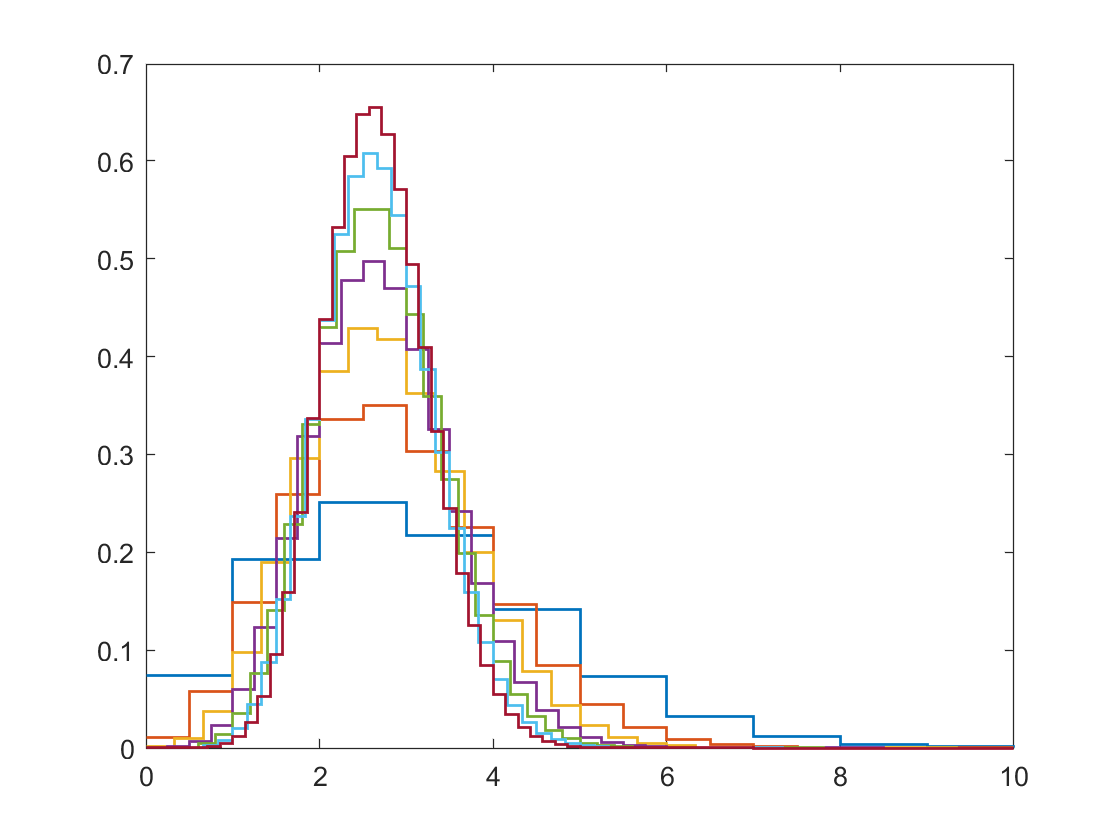

X = 2.6;
Y = 5.9;

res = 1;
xmax = 10;
xmin = 0;
x = xmin:res:xmax;

logP = makedist("Poisson",'lambda',X);

day1 = pdf(logP,x);
day1 = day1/sum(day1);
dayn = day1;

stairs(x,day1,"LineWidth",1)
hold on

for i = 2:7
    dayn = conv(dayn,day1,"full");
    
    x_n = xmin:res/i:xmax;
    stairs(x_n,i*dayn,"LineWidth",1)
end

%by plotting i*dayn, I'm ensuring the area under the curve is still equal
%to 1, since the resolution step size is 1/i

hold off

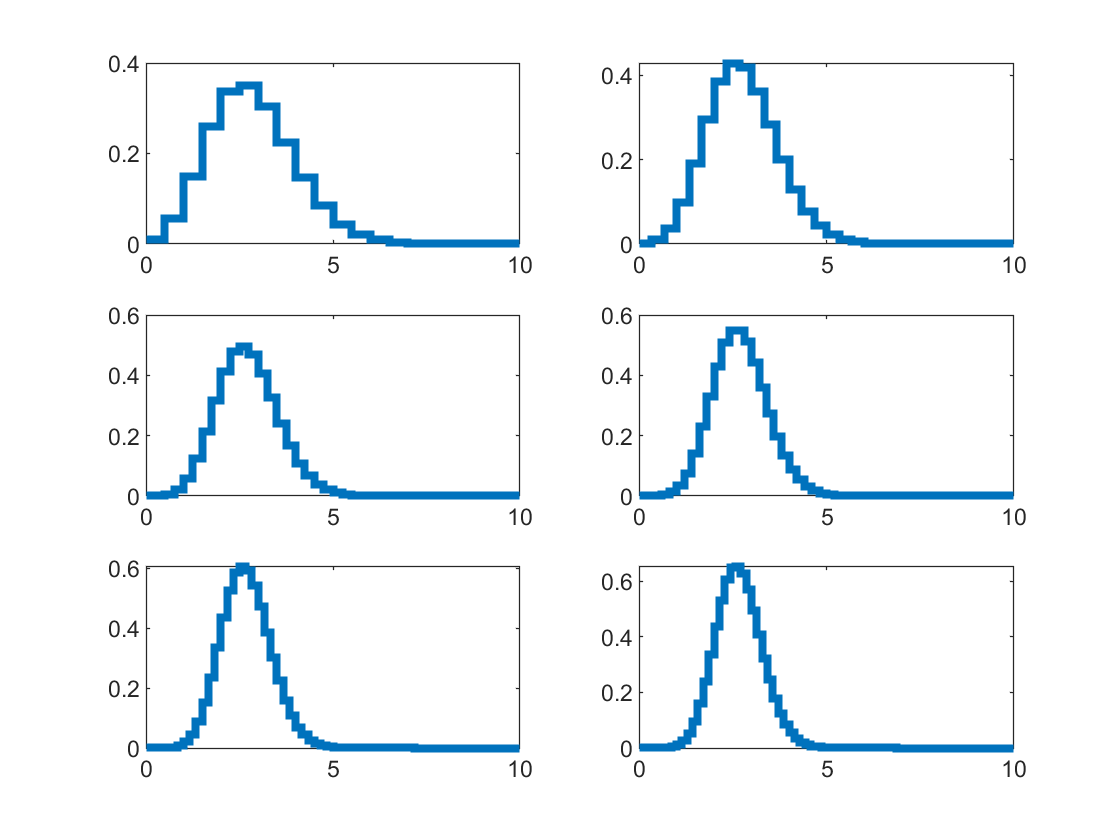


day1 = pdf(logP,x);
day1 = day1/sum(day1);
dayn = day1;

for i = 2:7
    dayn = conv(dayn,day1,"full");
    
    subplot(3,2,i-1)
    x_n = xmin:res/i:xmax;
    stairs(x_n,i*dayn,"LineWidth",3)
end
hold off

Talk about explanations and stuff -- more plots (log, gaussian) to make point?

## D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation. [In reality the number of gamma-rays seen from a source will also fluctuate, but we're going to ignore that complication for a couple of labs.]

- you see Y*N gamma rays... 

# Problem 2

Pick a skewed continuous distribtuion, such as a Rayleigh, that describes your background over some observing interval.

## A) Show how the distribution changes as you average over more observing intervals.

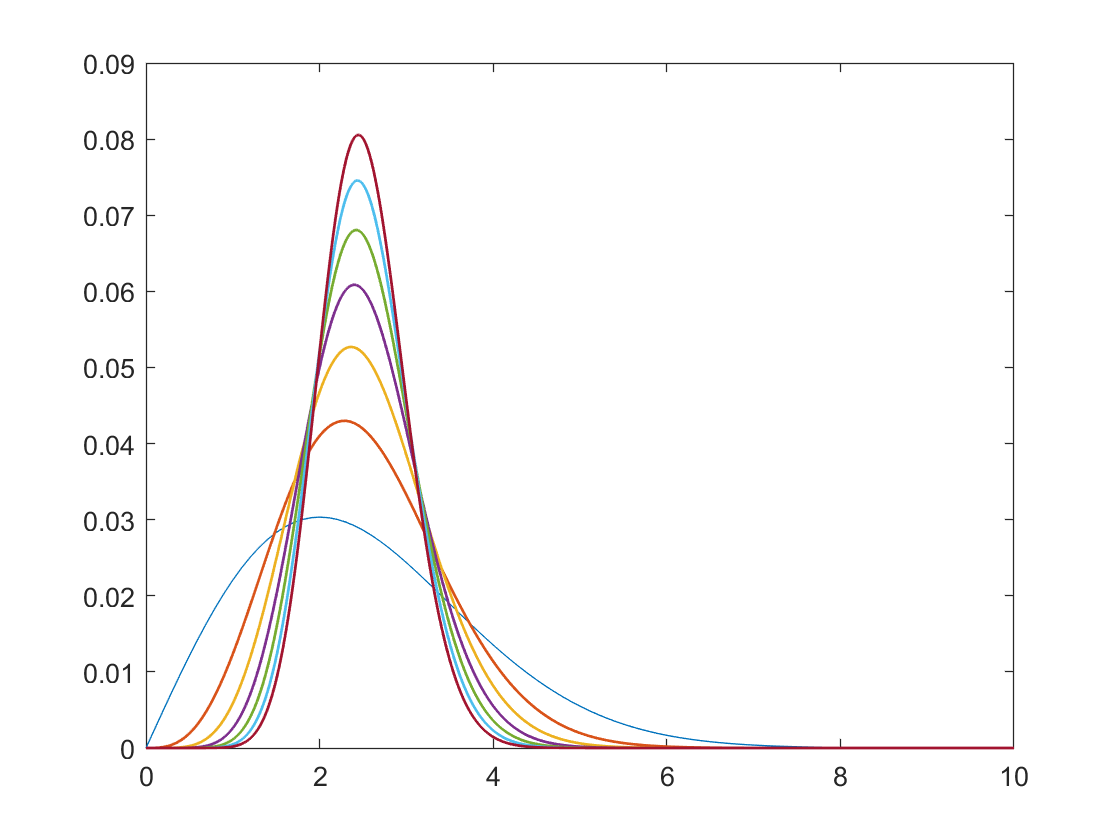

ray_res = 0.1;
xmax = 10;
xmin = 0;
x = xmin:ray_res:xmax;

ray = makedist("Rayleigh","b",2);

base_ray = pdf(ray,x);
base_ray = base_ray/sum(base_ray);
avgd = base_ray;

subplot(1,1,1)
plot(x,base_ray)
hold on

for i = 2:7
    avgd = conv(avgd,base_ray,"full");
    
    x_k = xmin:ray_res/i:xmax;
    plot(x_k,i*avgd,"LineWidth",1)
end

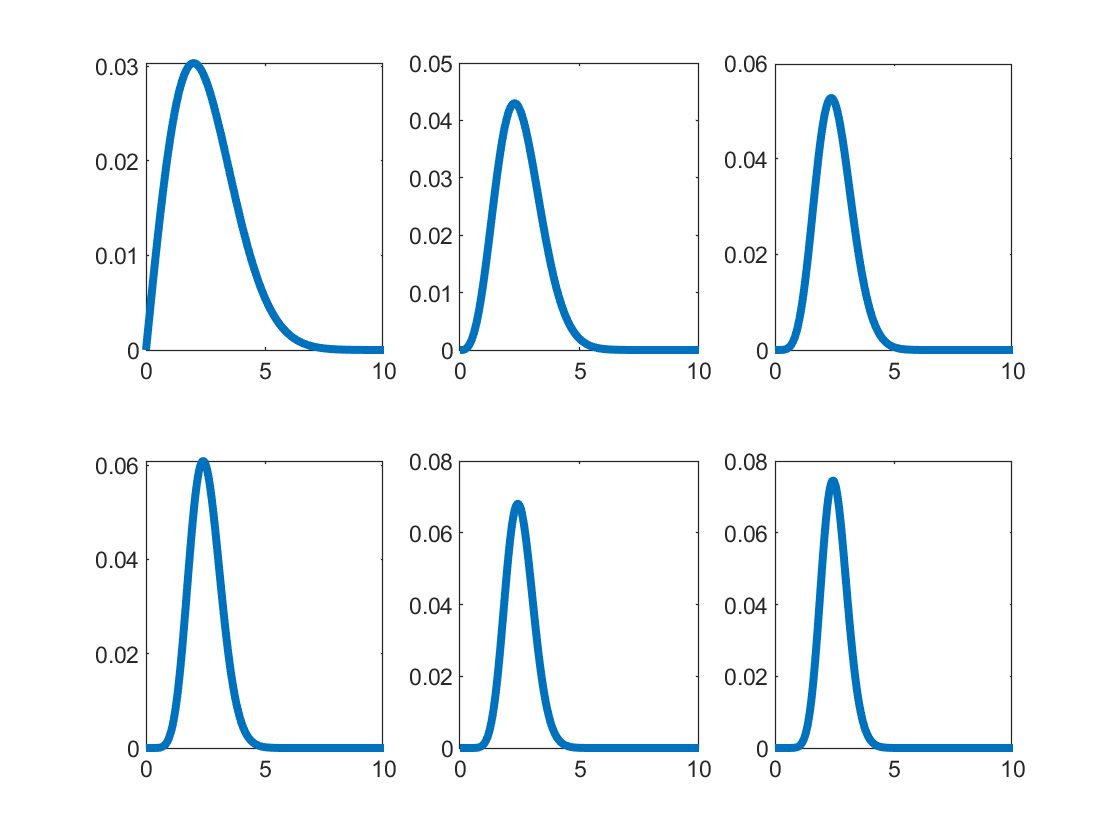


avgd = base_ray;

subplot(2,3,1)
plot(x,base_ray,"LineWidth",3)

for k = 2:6
    avgd = conv(avgd,base_ray,"full");
    
    subplot(2,3,k)
    x_k = xmin:ray_res/k:xmax;
    plot(x_k,k*avgd,"LineWidth",3)
end

## B) Discuss how the shape changes. Does it approach a Gaussian distribution? If yes, after how many intervals?

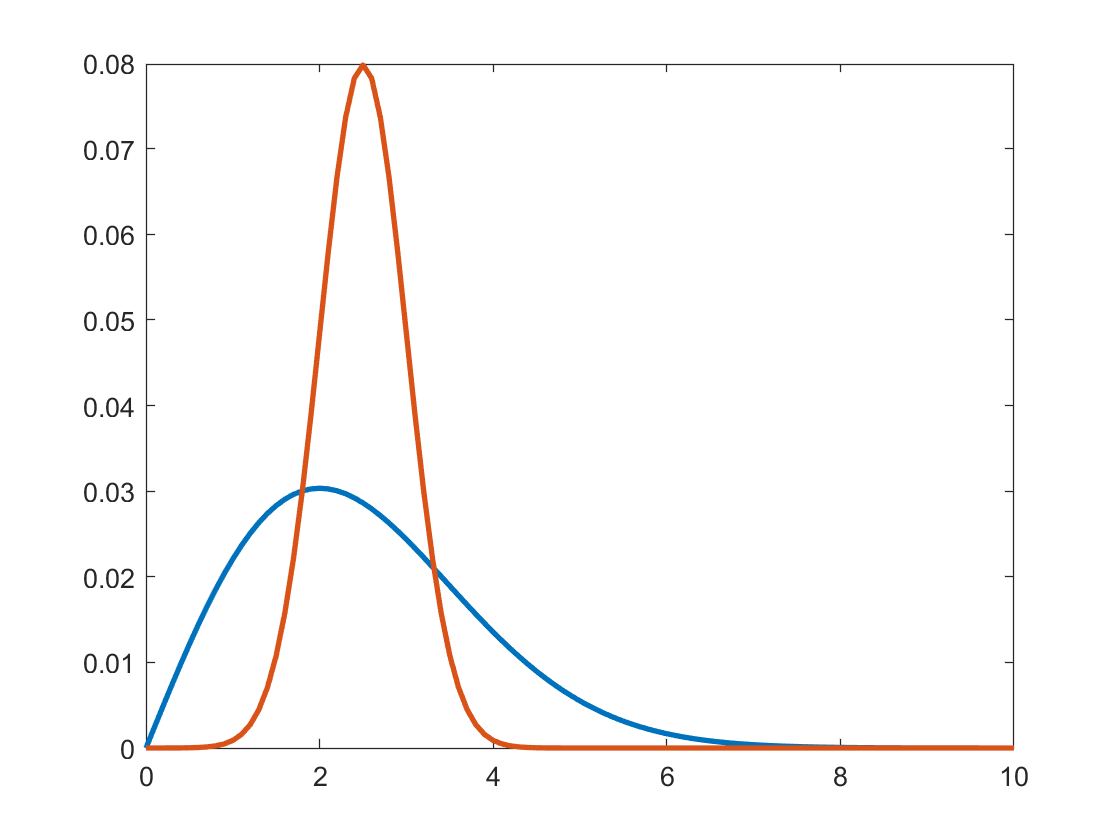

ray_res = 0.1;
xmax = 10;
xmin = 0;
x = xmin:ray_res:xmax;

ray = makedist("Rayleigh","b",2);

base_ray = pdf(ray,x);
base_ray = base_ray/sum(base_ray);
avgd = base_ray;

gaussian_dist = makedist("Normal","mu",2.5,"sigma",0.5);
gauss = pdf(gaussian_dist,x)/sum(pdf(gaussian_dist,x));

subplot(1,1,1)
plot(x,base_ray,"LineWidth",2)
hold on
plot(x,gauss,"LineWidth",2)
hold off

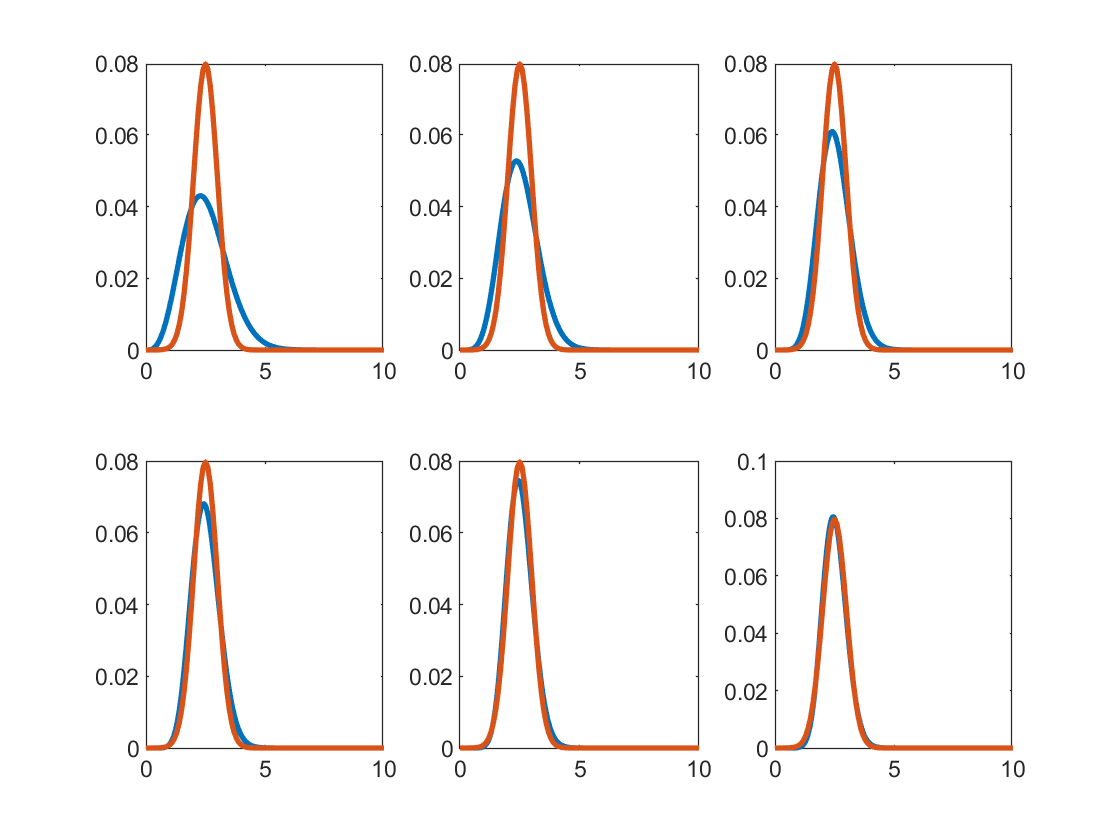


for k = 2:7
    avgd = conv(avgd,base_ray,"full");
    
    subplot(2,3,k-1)
    x_k = xmin:ray_res/k:xmax;
    plot(x_k,k*avgd,"LineWidth",2)
    hold on
    plot(x,gauss,"LineWidth",2)
    hold off
end

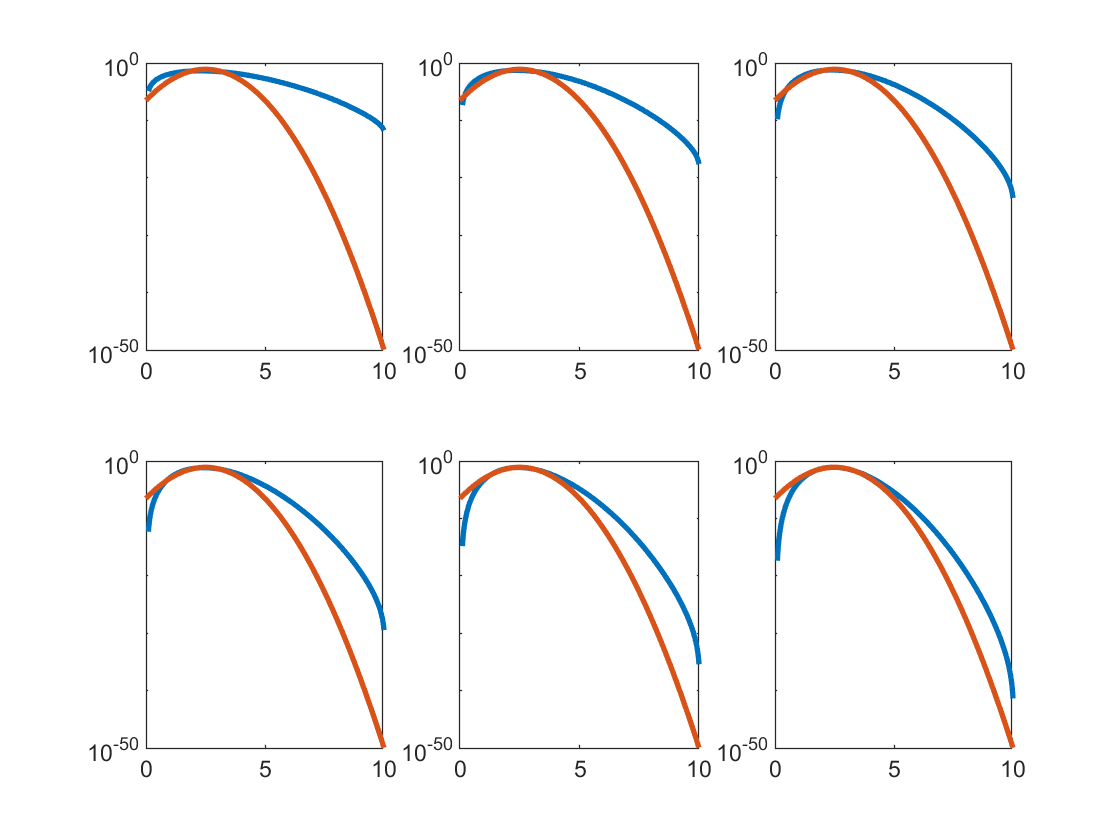

avgd = base_ray;

for j = 2:7
    avgd = conv(avgd,base_ray,"full");
    
    subplot(2,3,j-1)
    x_k = xmin:ray_res/j:xmax;
    plot(x_k,j*avgd,"LineWidth",2)
    hold on
    plot(x,gauss,"LineWidth",2)
    set(gca,'YScale','log')
    hold off
end

# Problem 3

The discovery of optical/infra-red counterparts of Neutron star mergers initially detected with gravity-waves is one of the great discoverys in the last few years ([wikipedia](https://en.wikipedia.org/wiki/GW170817), [scientific paper](https://arxiv.org/abs/1710.05833)), and has ushered in the age of "multi-messenger astrophysics." The science that can be done by matching a gravity-wave signal (directly measures the mass of the neutron stars and their distance) with the optical emisson (redshift, nuclear astrophysics of the resulting explosion) is *staggering*. Lots of science from how the heaviest elements are formed to constraints on Dark Energy.

We're going to explore one of the analysis questions that comes up when looking for the optical counterparts (a new optical source) of a gravity wave signal. For this problem let's assume that we are using an optical telescope with a thermal noise background from the CCD (dark current, particularly an issue with older CCDs and/or infra-red CCDs). After flat-fielding, the background appears as a zero-mean Gaussian with constant width over the image.

## Version 1

You have an alert from [LIGO](https://www.ligo.caltech.edu) that is also seen in with the X-ray/ultra-violet satellite [SWIFT](https://swift.gsfc.nasa.gov). SWIFT gives you a very precise location, so you take an image of that part of the sky. But because of SWIFT's accuracy, you know which pixel in your image to look for a counterpart in.

### A) From looking at all the other pixels in your image, you can measure the width of the background Gaussian distribution X (pick something). Assuming you see a signal of strength Y (pick a floating-point number; optical CCDs are not sensitive enough to count photons so the readings are floating point brightnesses, not integer photons). Calculate the significance of your detection. Can you claim a discovery (traditionally 5-sigma or more)?

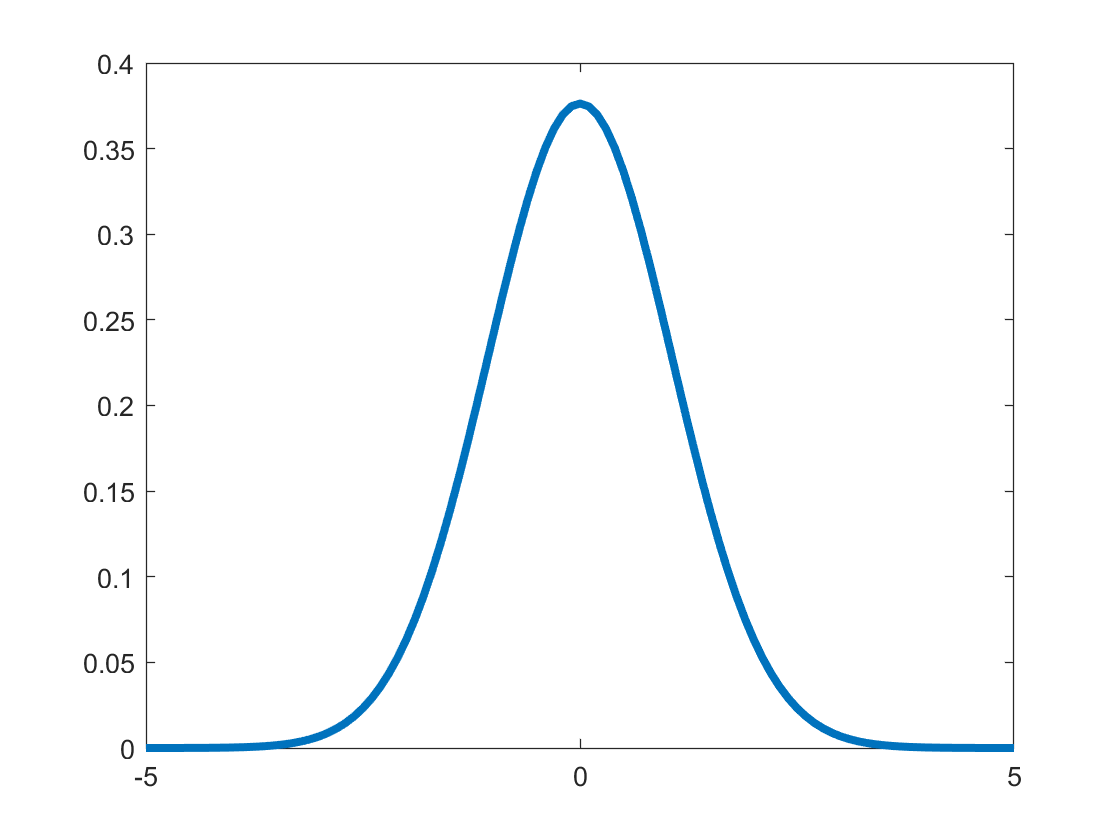

X = 1.06;
Y = 3.56;
xes = -5:0.1:5;

subplot(1,1,1)
background = makedist("Normal","mu",0,"sigma",X);
bg = pdf(background,xes);
plot(xes,bg,"LineWidth",3)

prob = cdf(background,Y)

prob =    0.999608153018779


sigma = norminv(prob)

sigma =    3.358490566037756


## **Version 2**

You have an alert from LIGO, but no associated detection from SWIFT. This could be because it is a black hole-black hole merger, a black hole-neutron star merger (neither seem to emit X-rays or UV light), or it could because SWIFT was indisposed at the time (wrong side of the earth in its orbit). Whatever the cause, you know what region of the sky to look in, but not which pixel.

### B) If you have to look for a signal in 10k pixels, what is the probability distribution of your background? (*Clearly* state the statistical question, then turn that into math using your background distribution from part 1 of this problem.)

Convolving my distribution 10000 times takes way too long, so to find the background distribution, I can use some knowledge of convolutions and of probability. 

My question: Given a set of 10,000 pixels, what does my background distribution look like and how likely is it that the background will look as or more signal-like than my signal? In this background, is my signal significant?

To give a vague impression of what 10,000 convolutions would look like, I'll convolve my distribution 10 times and see how the standard deviation and probability compares to my initial distribution. 

pd = makedist("Normal","mu",0,"sigma",1.06);
x = -5:0.1:5;
funct = pdf(pd,x);
funct = funct/sum(funct);
combined = funct;

prob = cdf(pd,3.56)

prob =    0.999608153018779



for i = 2:10
    combined = conv(combined,funct,"full");
    
    prob = cdf("Normal",3.56,0,std(combined))
end

prob =      1


prob =      1


prob =      1


prob =      1


prob =      1


prob =      1


prob =      1


prob =      1


prob =      1



subplot(1,1,1)
standard_dev = std(combined)

ans =    0.002723384906358


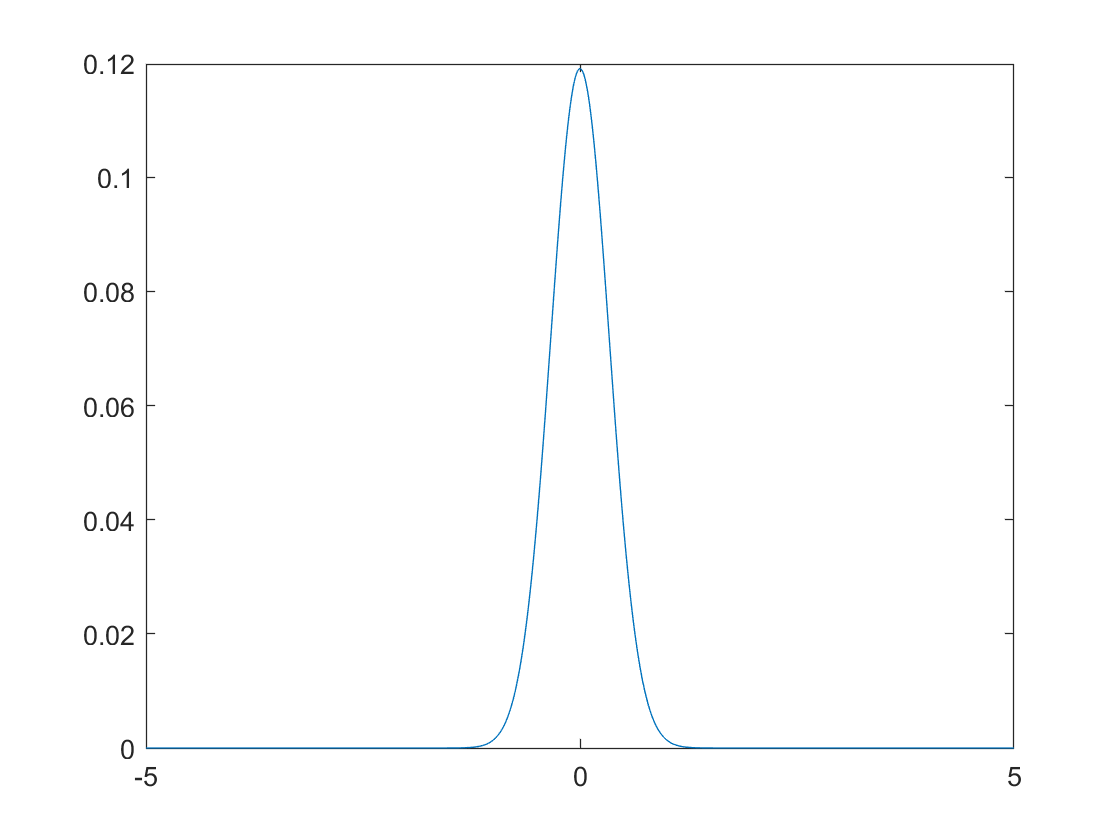

cbx = -5:0.1/10:5;  
plot(cbx,combined*10,"LineWidth",3)

As you can see, even after only 10 convolutions, the graph of the distribution is *much* thinner than before, with a standard deviation of 0.003. This indicates that, since the distribution will become thinner with each convolution, the background after 10,000 convolutions will essentially be a sharp peak at 0, with very little width. 

<On probability and sigma>

### C) Taking your brightest candidate signal from the region (assume it has the same signal as in part 1), calculate the significance of your detection.

<code to find sigma>

# Problem 4

The statistical issue we were exploring in the previous problem is called a **trials factor** (sometimes known as a look-elsewhere effect). This is an important effect, as if you search through a million locations, you would expect to se ~1 one in a million event. However, it is also often over estimated how big an impact this makes on the sensitivity of a search. So in this part of the lab we are going to invert the problem.

Let us again assume we have a Gaussian background (same parameters as Problem 3).

## A) Calculate the signal required for a 5-sigma detection in Version 1

## B) Calculate the signal required for a 5-sigma detection in Version 2

## C) Discuss how much brighter the signal must be for discoverey if you have a trials factor of 10k. Looking at your probability distributions, explain why the sensitivity penalty due to a trials factor is so low.

## D) If you changed the trials factor significantly (orders of magnitude), how large is the effect on your 5-sigma sensitivity threshold?

## Extra credit: If you had a different distribution shape (non-Gaussian), how would that affect the sensitivity penalty of many trials? Clearly explain.